clear;
clc;
% letSound = 1 启用声音播放 不建议
letSound = 0;
[music,Fs] = audioread('testMusic.mp3');
% 取单声道
musicSingle=  music(:,1);
% noiseLeval 噪音强度 -2dB
noiseLeval = 10^(-2/10);

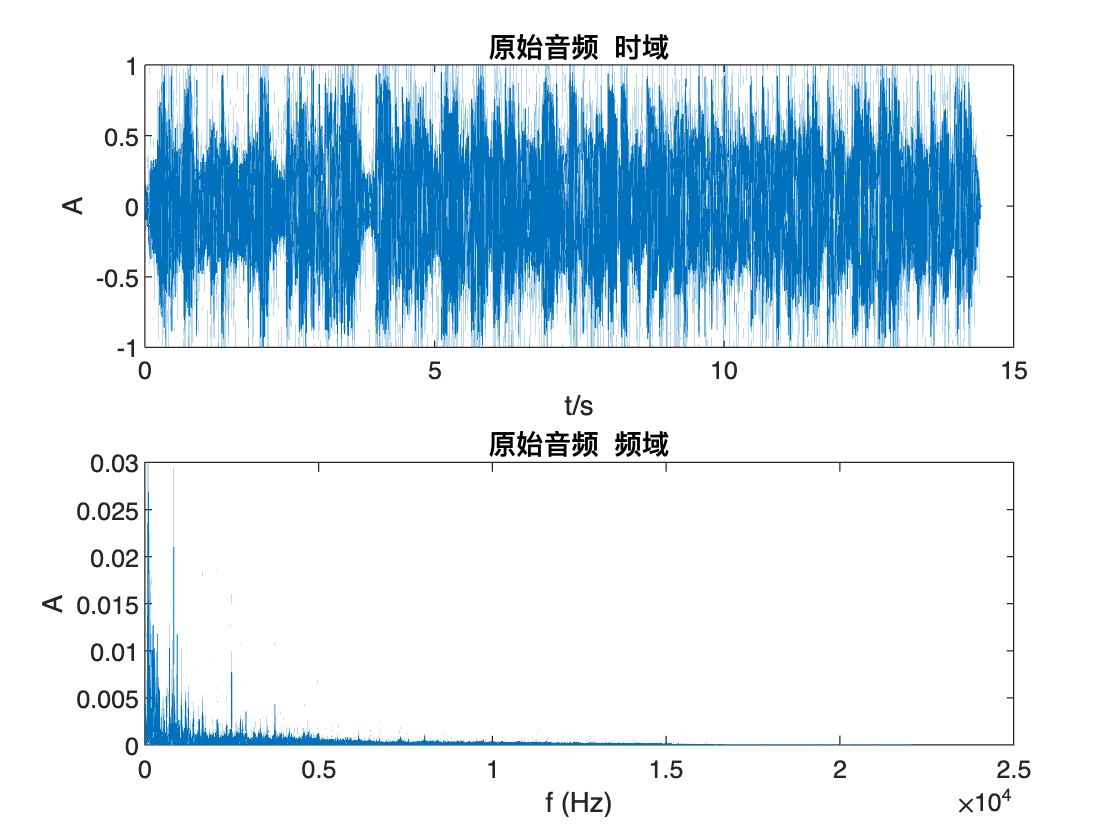

% 高斯白噪声
whiteNoise = (2*rand(length(musicSingle),1)-1)*noiseLeval;
% 时间序列
t = (1:length(musicSingle))'/Fs;
% 噪声 200Hz
noise200 = noiseLeval*sin(2*pi*(200)*t);
% 15kHz 17kHz 19kHz 正弦信号
noise17k = noiseLeval*sin(2*pi*(17*10^3)*t);
noise19k = noiseLeval*sin(2*pi*(19*10^3)*t);
noise15k = noiseLeval*sin(2*pi*(15*10^3)*t);

plotFFT(musicSingle,Fs,'原始音频')

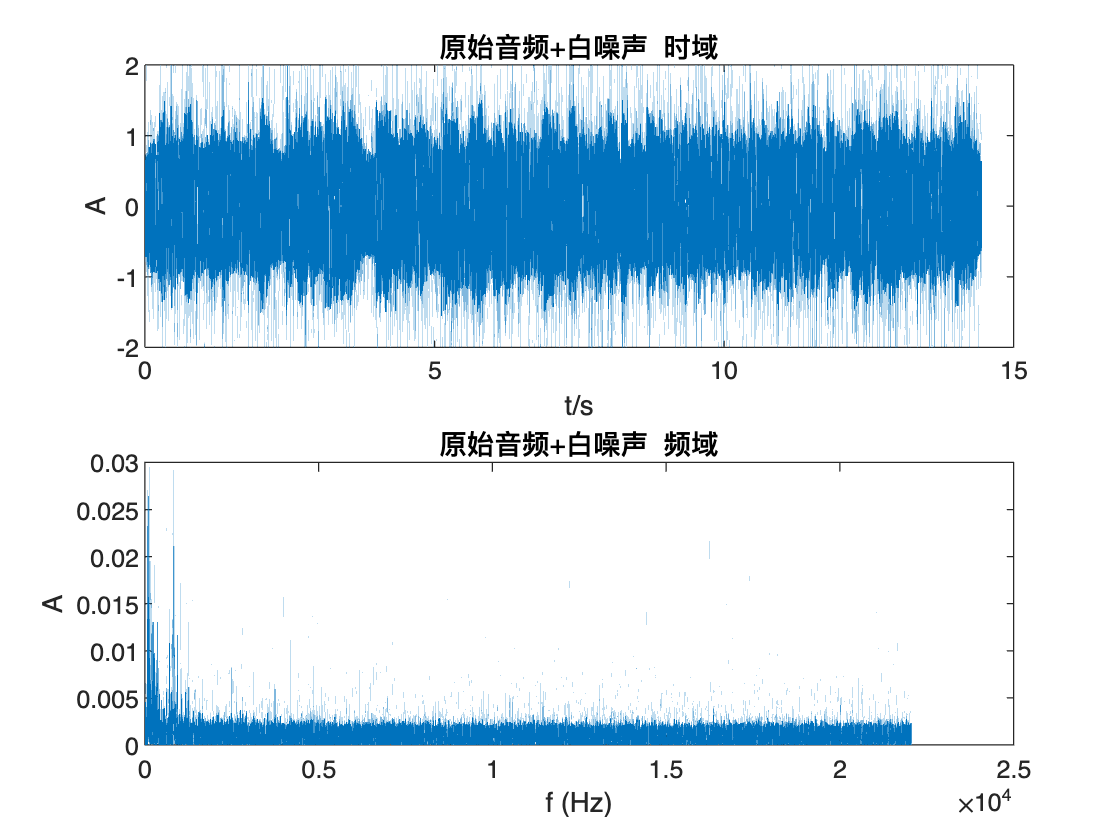


addWhiteNoise = musicSingle+whiteNoise;
plotFFT(addWhiteNoise,Fs,'原始音频+白噪声')

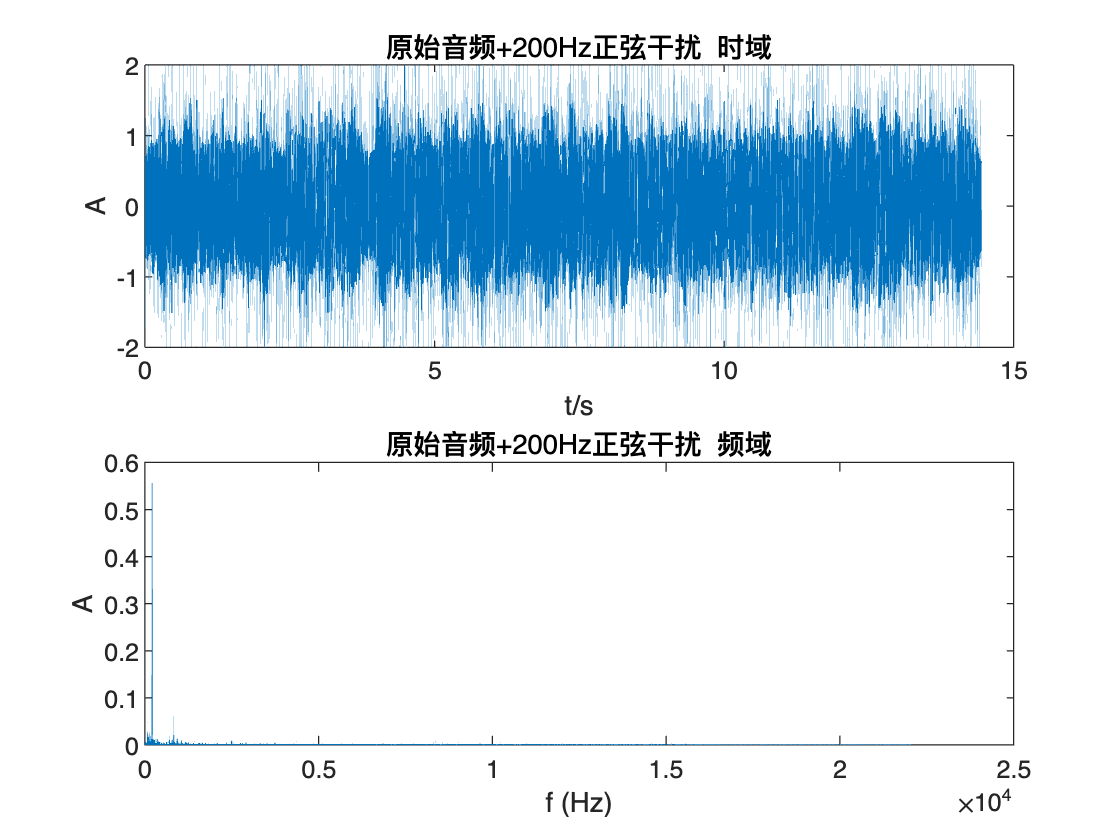


addNosise200 = musicSingle+noise200;
plotFFT(addNosise200,Fs,'原始音频+200Hz正弦干扰')

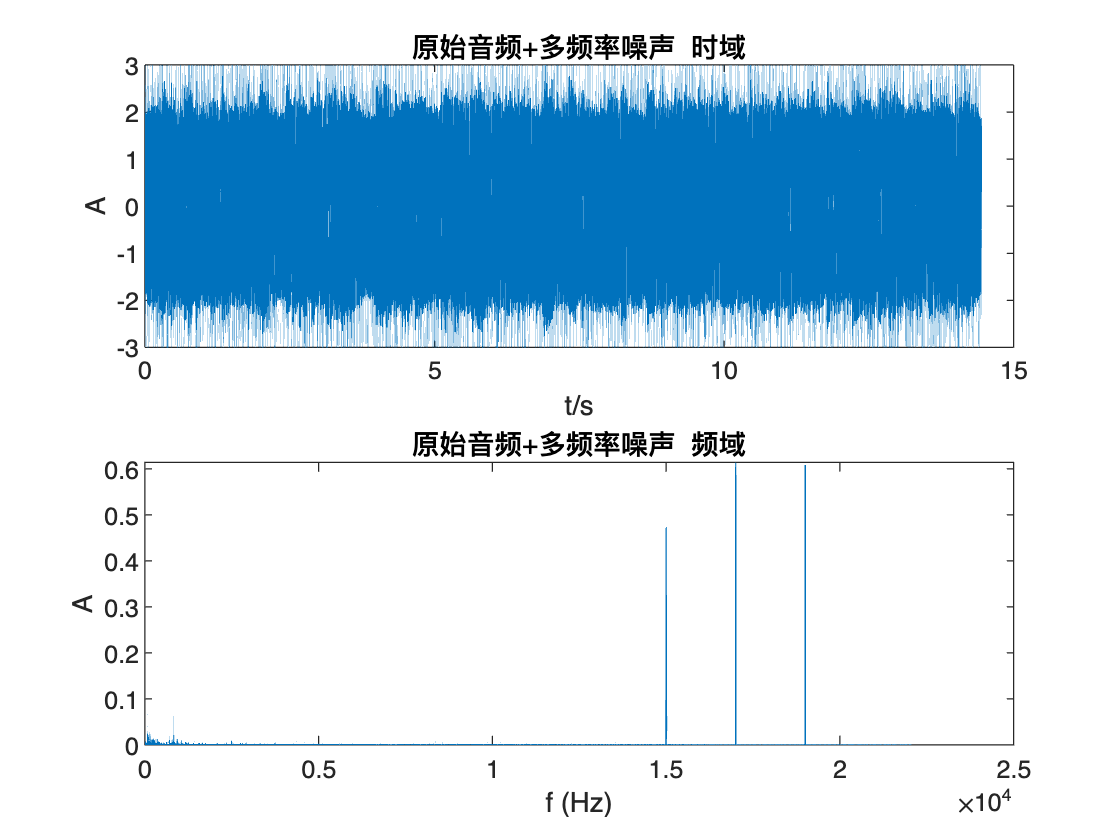


addNosiseMix = musicSingle+noise15k+noise17k+noise19k;
plotFFT(addNosiseMix,Fs,'原始音频+多频率噪声')


if letSound == 1
    sound(musicSingle,Fs);
    sound(addWhiteNoise,Fs);
    sound(addNosise200,Fs);
    sound(addNosiseMix,Fs);
end

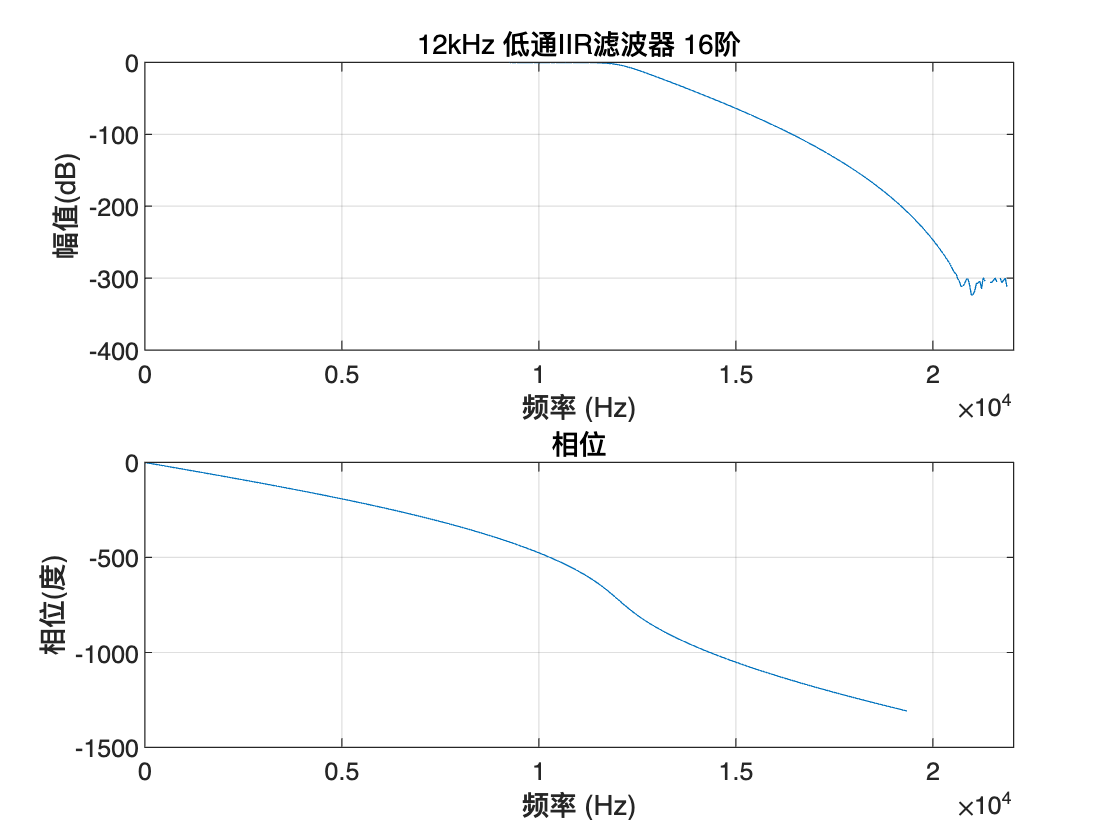

% 12kHz 低通IIR滤波器 16阶
[b,a] = butter(16,(12*10^3)/(Fs/2));
dataOutButter = filter(b,a,addNosiseMix);
figure;
freqz(b,a,[],Fs)
title('12kHz 低通IIR滤波器 16阶')

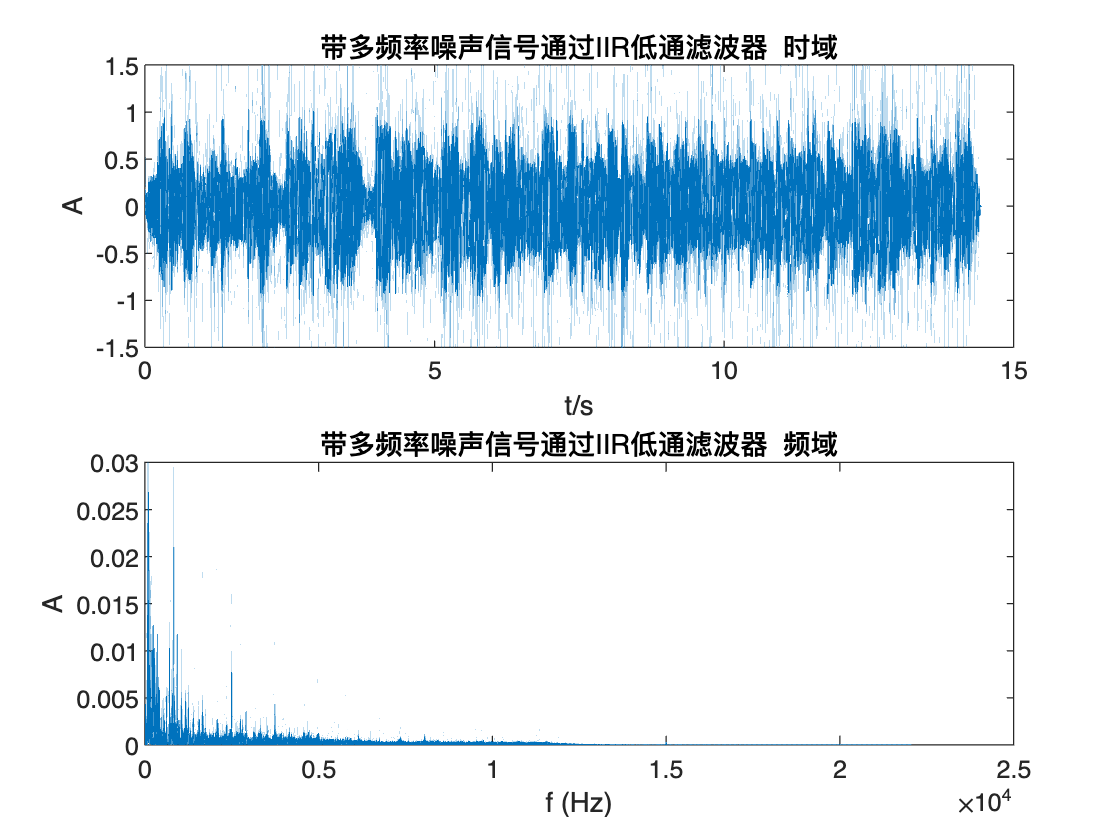


plotFFT(dataOutButter,Fs,'带多频率噪声信号通过IIR低通滤波器')

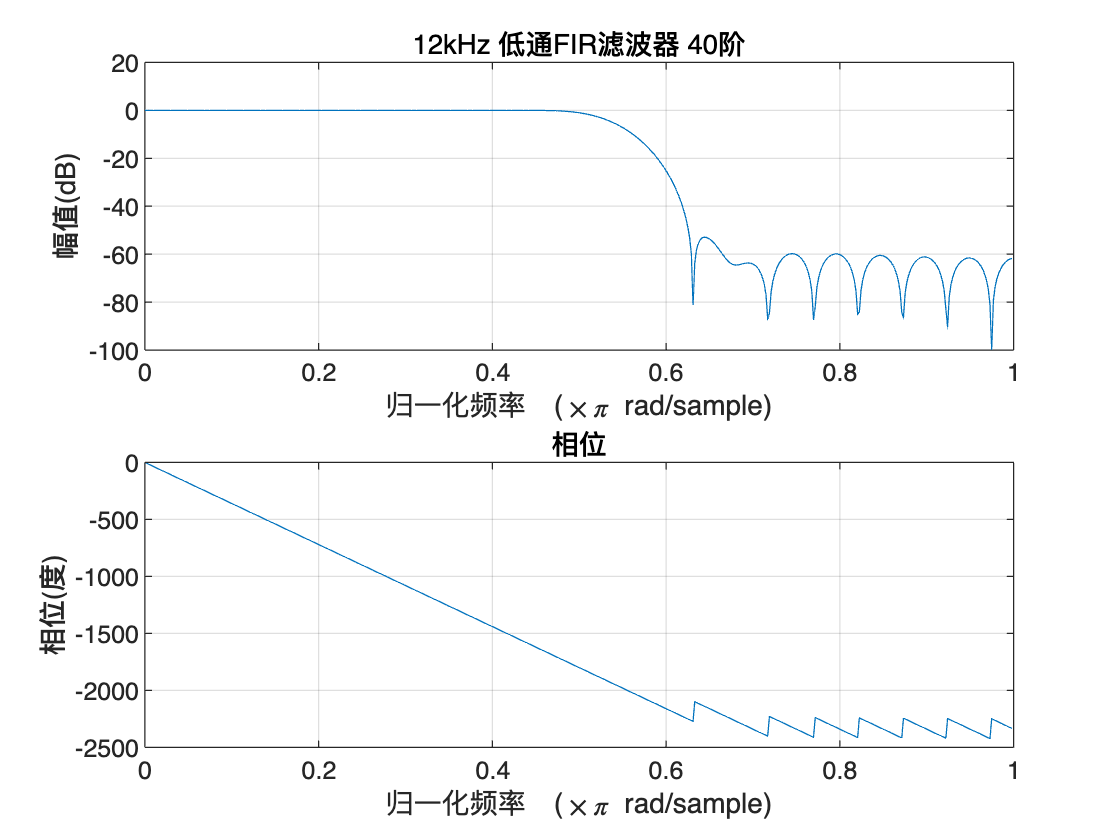


% 12kHz 低通FIR滤波器 40阶
bhi = fir1(40,(12*10^3)/(Fs/2),'low');
figure;
freqz(bhi,1)
title('12kHz 低通FIR滤波器 40阶')

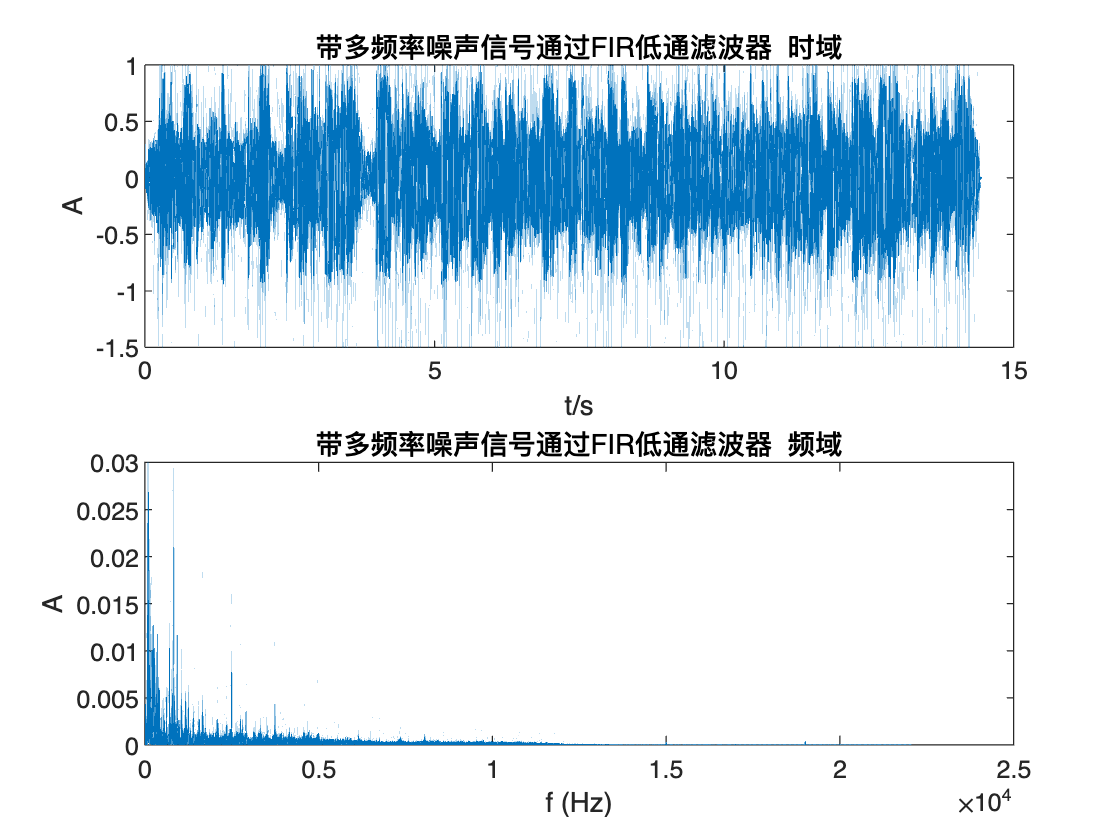

dataOutFIR = filter(bhi,1,addNosiseMix);
plotFFT(dataOutFIR,Fs,'带多频率噪声信号通过FIR低通滤波器')


if letSound == 1
    sound(dataOutButter,Fs);
    sound(dataOutFIR,Fs);
end

audiowrite("addWhiteNoise.wav",addWhiteNoise,Fs)
audiowrite("addNosise200.wav",addNosise200,Fs)
audiowrite("addNosiseMix.wav",addNosiseMix,Fs)
audiowrite("dataOutFIR.wav",dataOutFIR,Fs)